Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Initialize by cleaning memory and widows

clear all;
close all;

#### Initialize parameters of the model and instantiate model class

ell     = 1.0;
m       = 1.0;
gravity = 9.81;
ode     = DoubleSlider( ell, m, gravity );

#### Initialize the solver class

solver_1 = ImplicitEuler();
solver_2 = CrankNicolson();
solver_3 = GaussLegendre4();

LEGEND = {'ImplicitEuler', 'CrankNicolson', 'GaussLegendre4'};

solver_1.setODE(ode);
solver_2.setODE(ode);
solver_3.setODE(ode);

#### **Select the range and the sampling point for the numerical solution**

Tmax = 7.5;
h    = 0.05;
tt   = 0:h:Tmax;

#### Set consistent initial conditions

angle     = 0.0*pi;
speed     = 0.0;

x_0       = -ell*cos(angle)/2;
y_0       = ell*sin(angle)/2;
theta_0   = angle;
u_0       = speed*ell*cos(angle)/2;
v_0       = speed*ell*sin(angle)/2;
omega_0   = speed;
lambda_10 = -ell*m*speed^2*sin(angle)/4 + sin(angle)^2*gravity*m/2;
lambda_20 = cos(angle)*m*(ell*speed^2 - 2*sin(angle)*gravity)/4;
ini       = [ x_0; y_0; theta_0; ...
              u_0; v_0; omega_0; ...
              lambda_10; lambda_20 ];

#### **Compute numerical solution**

sol_1 = solver_1.advance( tt, ini );

NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver

sol_2 = solver_2.advance( tt, ini );

NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver

sol_3 = solver_3.advance( tt, ini );

NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1
NewtonSolver

#### Extract solution

x_1     = sol_1(1,:);
y_1     = sol_1(2,:);
theta_1 = sol_1(3,:);

x_2     = sol_2(1,:);
y_2     = sol_2(2,:);
theta_2 = sol_2(3,:);

x_3     = sol_3(1,:);
y_3     = sol_3(2,:);
theta_3 = sol_3(3,:);

#### Plot the solution

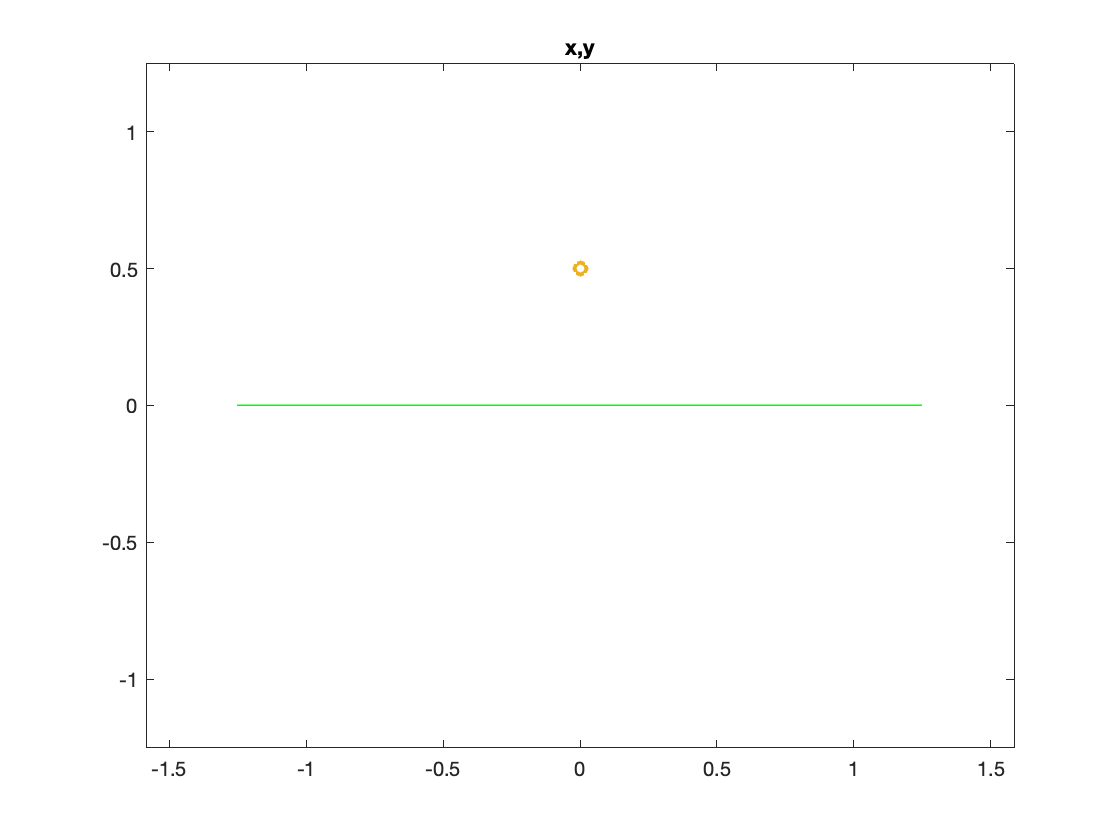

h = figure();
a = -1.25*ell:0.01:1.25*ell;
plot( 0.0.*a, a, '-', 'Linewidth', 1, 'Color','green' );
hold on;
plot( a, 0.0.*a, '-', 'Linewidth', 1, 'Color','green' );
% get mass position

axis equal
plot( x_1, y_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_2, y_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_3, y_3,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
title('x,y');

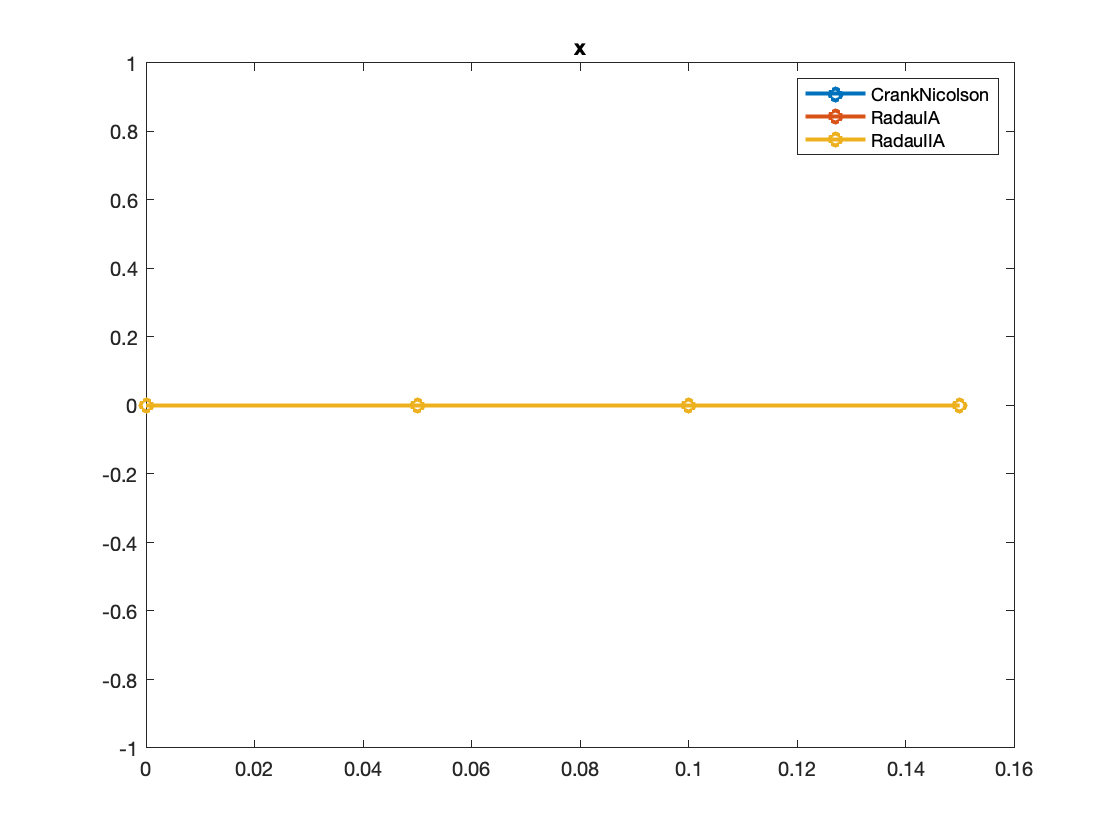

h = figure();
plot( tt, x_1.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x_2.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x_3.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x');

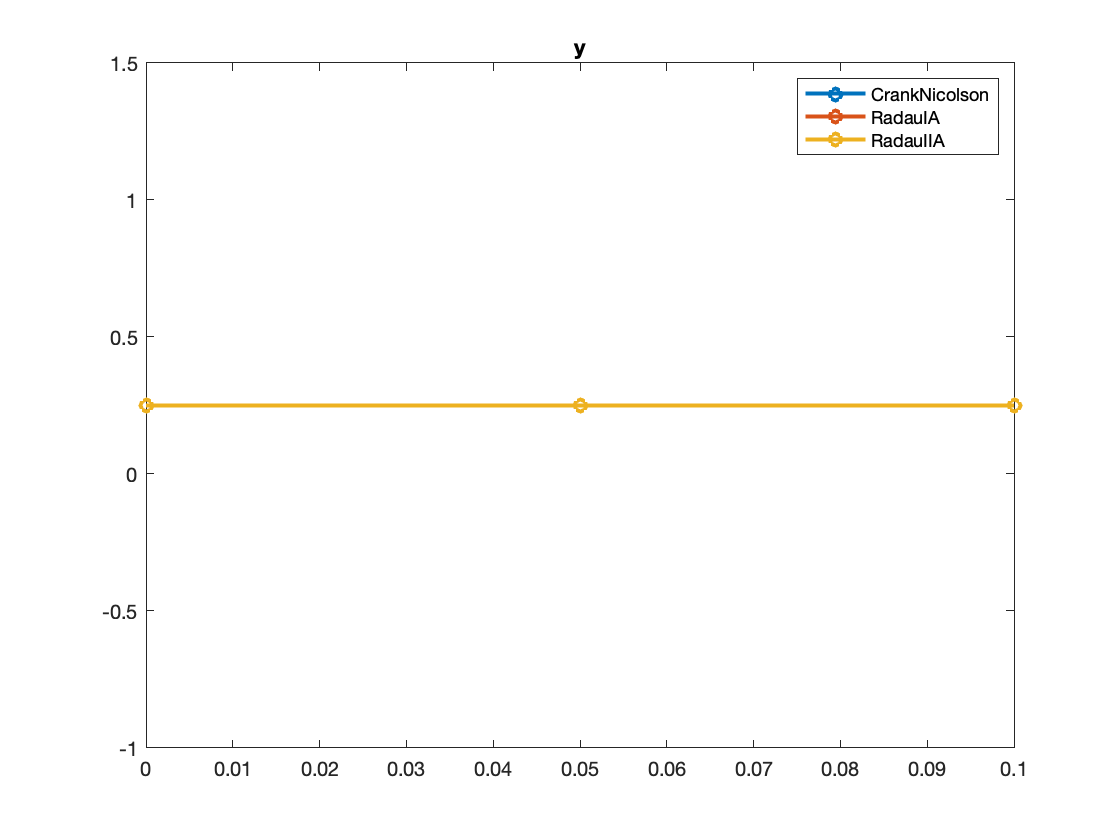

h = figure();
plot( tt, y_1.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, y_2.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, y_3.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('y');

### Make animation of the solution

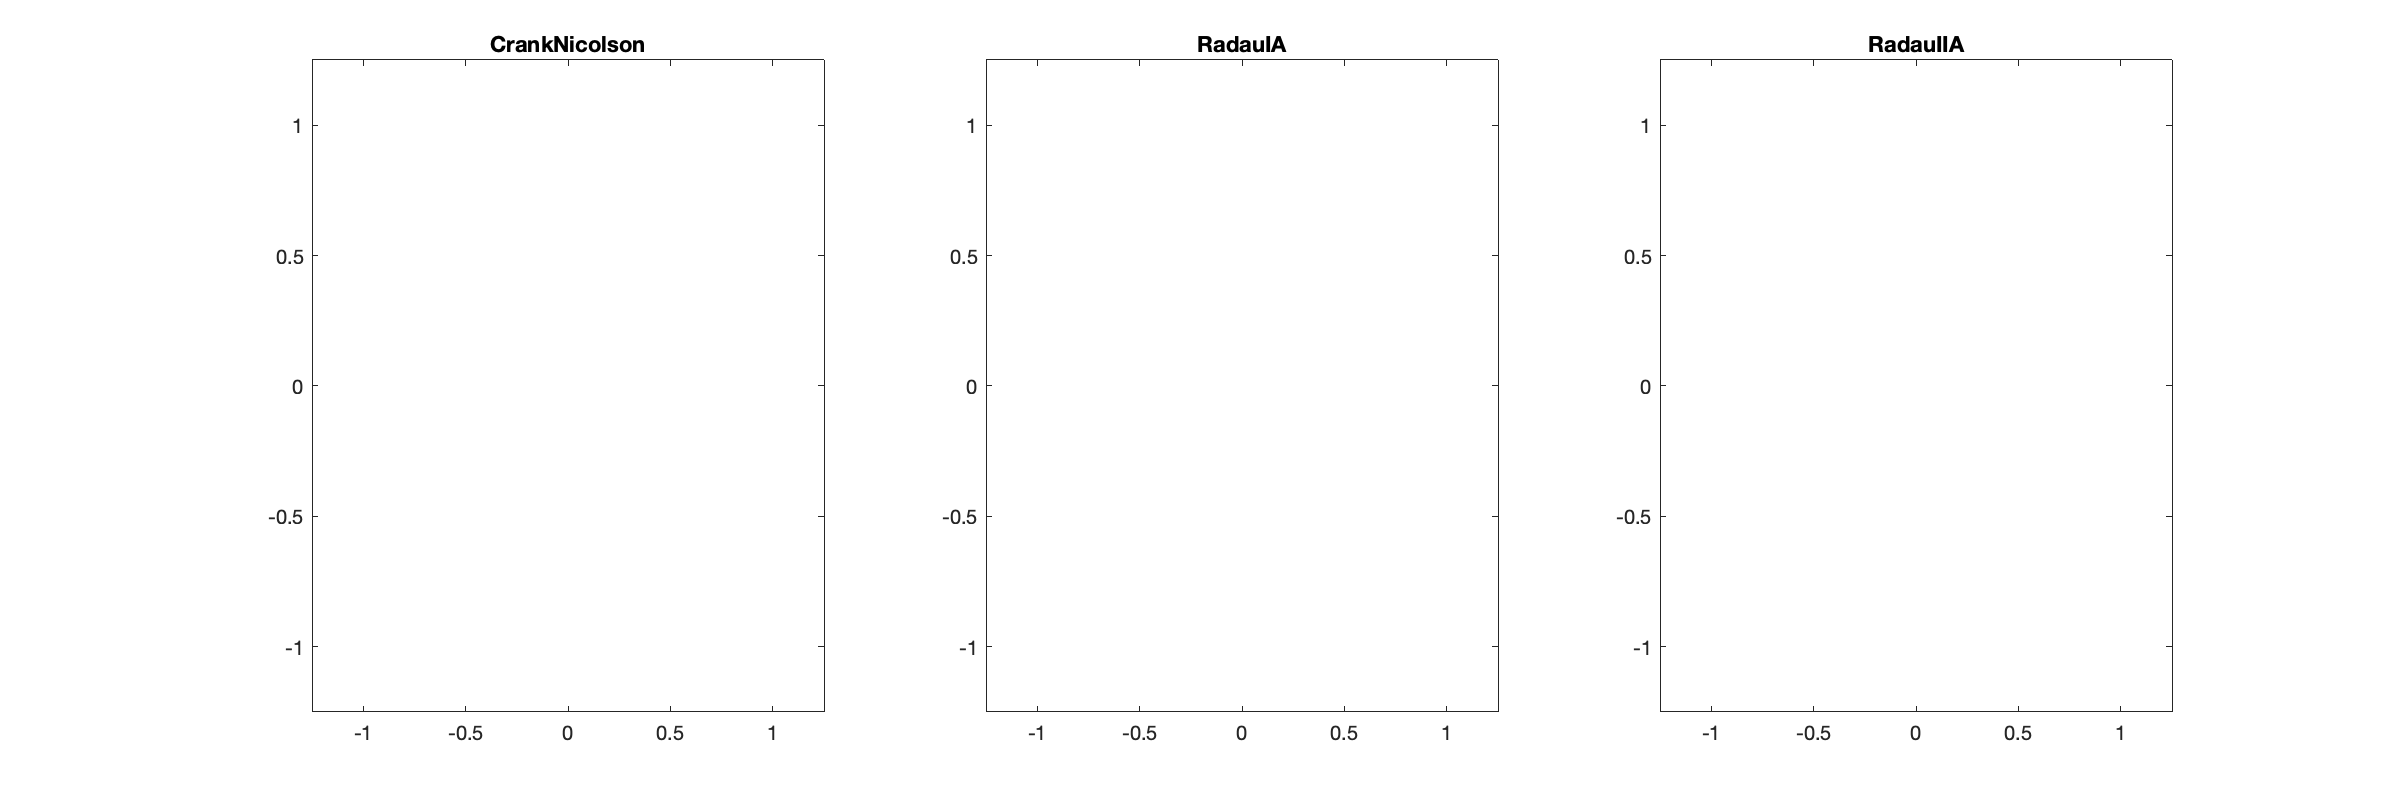

if true
  figure('Position', [1 1 1200 400]);
  for k=1:5:length(tt)
    subplot(1,3,1);
    ode.plot( tt(k), sol_1(:,k));
    title(LEGEND{1});
    subplot(1,3,2);
    ode.plot( tt(k), sol_2(:,k));
    title(LEGEND{2});
    subplot(1,3,3);
    ode.plot( tt(k), sol_3(:,k));
    title(LEGEND{3});
    drawnow limitrate;
    pause(0.01);
  end
end

### Compute solutions activating projection

sol_1 = solver_1.advance( tt, ini, true, true );

NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


  5%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 10%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 15%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 20%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 25%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 30%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 35%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 40%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 45%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 50%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 55%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 60%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 65%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 70%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 75%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 80%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 85%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 90%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 95%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


100%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


sol_2 = solver_2.advance( tt, ini, true, true );

NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


  5%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 10%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 15%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


 20%
NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


NewtonSolver: Bad initial point!
solveStepByNewton do not converge ierr = 1


sol_3 = solver_3.advance( tt, ini, true, true );

### Extract computed solution

x_1     = sol_1(1,:);
y_1     = sol_1(2,:);
theta_1 = sol_1(3,:);

x_2     = sol_2(1,:);
y_2     = sol_2(2,:);
theta_2 = sol_2(3,:);

x_3     = sol_3(1,:);
y_3     = sol_3(2,:);
theta_3 = sol_3(3,:);

#### Plot the solution

h = figure();
a = -1.25*ell:0.01:1.25*ell;
plot( 0.0.*1, a, '-', 'Linewidth', 1, 'Color','green' );
hold on;
plot( a, 0.0.*a, '-', 'Linewidth', 1, 'Color','green' );
% get mass position

axis equal
plot( x_1, y_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_2, y_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_3, y_3,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
title('x,y');
h = figure();
plot( tt, x_1.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x_2.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x_3.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x');
h = figure();
plot( tt, y_1.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, y_2.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, y_3.^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('y');

### Make animation of the solution

if true
  figure('Position', [1 1 1200 400]);
  for k=1:5:length(tt)
    subplot(1,3,1);
    ode.plot( tt(k), sol_1(:,k));
    title(LEGEND{1});
    subplot(1,3,2);
    ode.plot( tt(k), sol_2(:,k));
    title(LEGEND{2});
    subplot(1,3,3);
    ode.plot( tt(k), sol_3(:,k));
    title(LEGEND{3});
    drawnow limitrate;
    pause(0.01);
  end
end